**1.** Take a look to your RNAseq counts dataset.

rnaseq_data_path = 'data/Saccharomyces_RNAseq_RAW_counts.csv';
rnaseq_table = readtable(rnaseq_data_path);

**a)** How many genes are represented in your dataset? 

disp(length(rnaseq_table.GeneName));

        7126



**b) **How many biological replicates per experimental conditions were obtained in this study? 

We start by having a look at the column headers:

disp(rnaseq_table.Properties.VariableNames);

  Columns 1 through 7

    'GeneName'    'Control_Rep1'    'Control_Rep2'    'Control_Rep3'    'HighTemperature_R…'    'HighTemperature_R…'    'HighTemperature_R…'

  Columns 8 through 14

    'LowPH_Rep1'    'LowPH_Rep2'    'LowPH_Rep3'    'OsmoPressure_Rep1'    'OsmoPressure_Rep2'    'OsmoPressure_Rep3'    'Anaerobic_Rep1'

  Columns 15 through 16

    'Anaerobic_Rep2'    'Anaerobic_Rep3'



There are 16 columns, with one being `GeneName`. Looking at the remaining 15 columns, they end with `1, 2, 3`. This indicates **3** biological replicates per experimental condition.

**c)** How many genes were actually measured by RNAseq (non-zero reads)?

rnaseq_array = table2array(rnaseq_table(:,vartype('numeric')));
nonzero_rnaseq_array = rnaseq_array(all(rnaseq_array, 2),:);
disp(nnz(all(nonzero_rnaseq_array, 2)));

        5950



**d)** Normalize your read counts dataset, by first dividing the values by the mean expression level of each gene across samples, and then dividing each library (column) by the median of its previously normalized values.

normalized_array = nonzero_rnaseq_array./median(nonzero_rnaseq_array./geomean(nonzero_rnaseq_array, 2),1);

**e)** Visualize your read counts distributions using boxplots for the transformed log2 values (before and after normalization). What can you say about your dataset in terms of spanning (orders of magnitude), median expression values? **Are there any evident effects on the dataset with the proposed normalization method? If so, try to explain them.**

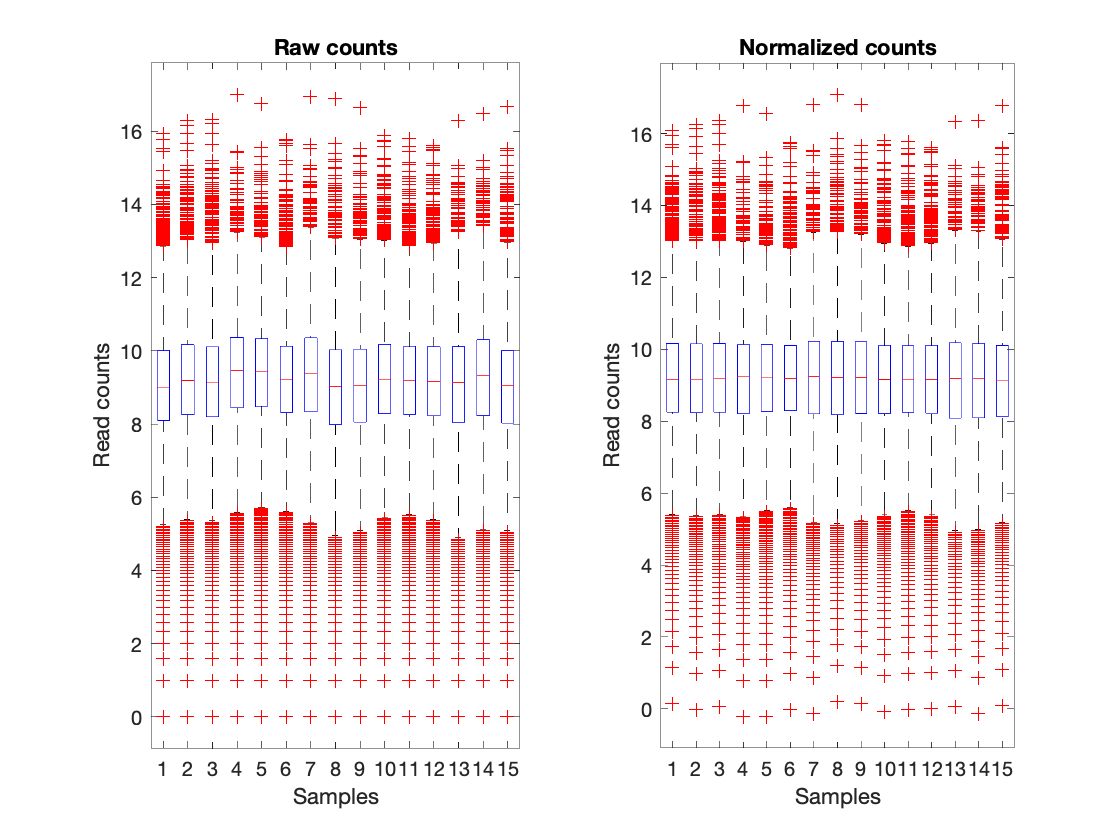

figure
% generate boxplot for log2 raw read counts
subplot(1,2,1);
boxplot(log2(nonzero_rnaseq_array))
title('Raw counts'); ylabel('Read counts'); xlabel('Samples');
% generate boxplot for log2 normalized counts
subplot(1,2,2);
boxplot(log2(normalized_array))
title('Normalized counts'); ylabel('Read counts'); xlabel('Samples');

The orders of magnitude have remained the same. The median values, however, are much more aligned. I chose to plot here only the genes that have nonzero values for all samples, since the log2 cannot be applied to 0 in a way that would show up on the plot. Moreover, since genes can have 0 values only for some samples, 

**As about plotting nonzero values, they are plotted in the exercise.**

**2.** Show your PCA results (PC1 vs PC2, displaying the percentage of variance for each in their respective axis labels).

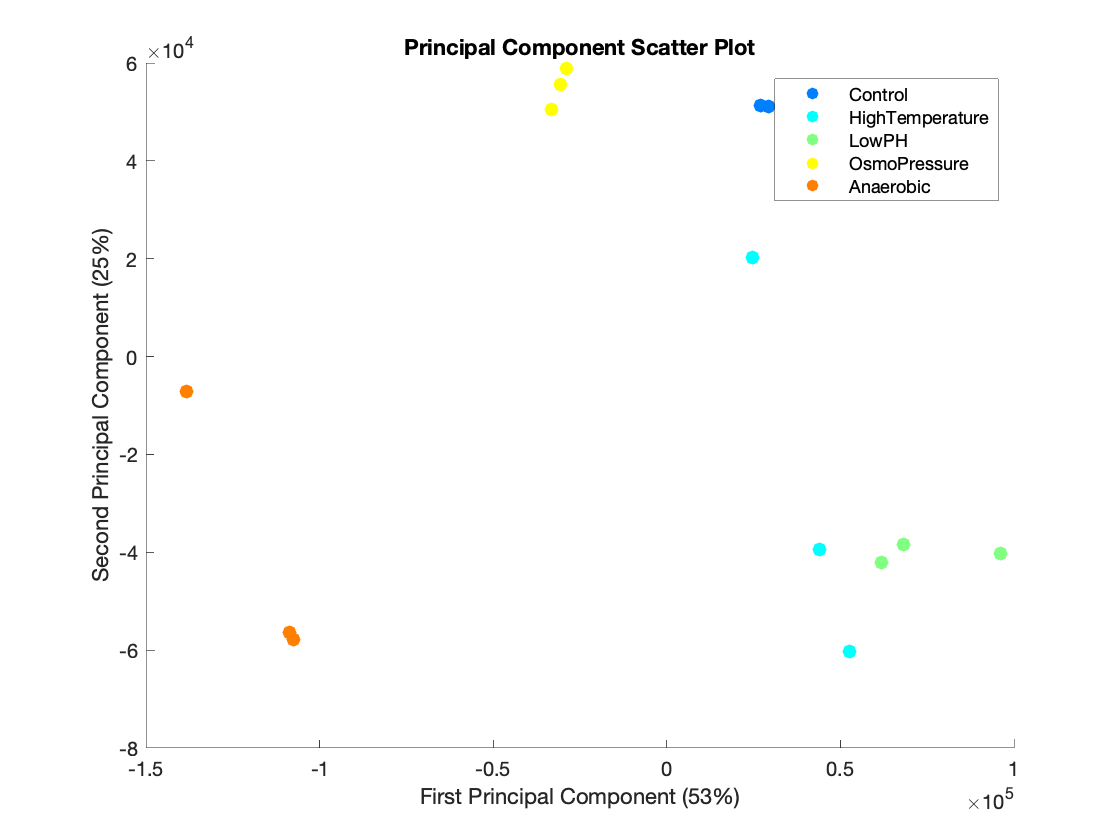

% perform PCA
[pc, zscores, pcvars] = pca(normalized_array');
% pick 5 colors to distinguish the 5 different conditions. Colormap returns
% the a mapped normalized RGB values for the specified amount of colorlevels
% in a given palette (jet in this case)
figure
colorScheme = colormap(jet(5));
hold on
% get a PCA plot showing PC1 and PC2 for all the samples in the 5 conditions
% Note: PC's are stored in the zscores table in which for each sample (columns) 
% the 15 first principal components are shown (rows).
condStr = {};
for i=1:5
    % get the condition name
    nameTMP = strsplit(rnaseq_table.Properties.VariableNames{(i-1)*3+2},'_');
    PC1     = zscores((i-1)*3+1:i*3,1);
    PC2     = zscores((i-1)*3+1:i*3,2);
    condStr = [condStr;nameTMP{1}];
    scatter(PC1,PC2,50,colorScheme(i,:),'fill');
end
pc1var = round(pcvars(1)/sum(pcvars)*100);
pc2var = round(pcvars(2)/sum(pcvars)*100);
xlabel(['First Principal Component (', num2str(pc1var), '%)']); 
ylabel(['Second Principal Component (', num2str(pc2var), '%)']);
title('Principal Component Scatter Plot');
legend(condStr)
hold off

**a)** Explain what the PCA results show.

The PCA plot shows how the different samples compare to each other in terms of overall similarity across the expression of all genes.

**b)** Are there any outlier samples in the dataset for any of the analyzed conditions?

One of the anaerobic samples appears much different than the other two. Moreover, the gene expression values vary between the high temperature samples (far apart in the plot).

**3.** Show the number of differentially expressed genes reference and a stress condition of your choice (High temperature, low pH, osmotic pressure). Use absolute log2 fold-change = 2 and 0.01 corrected p-value as your threshold parameters.

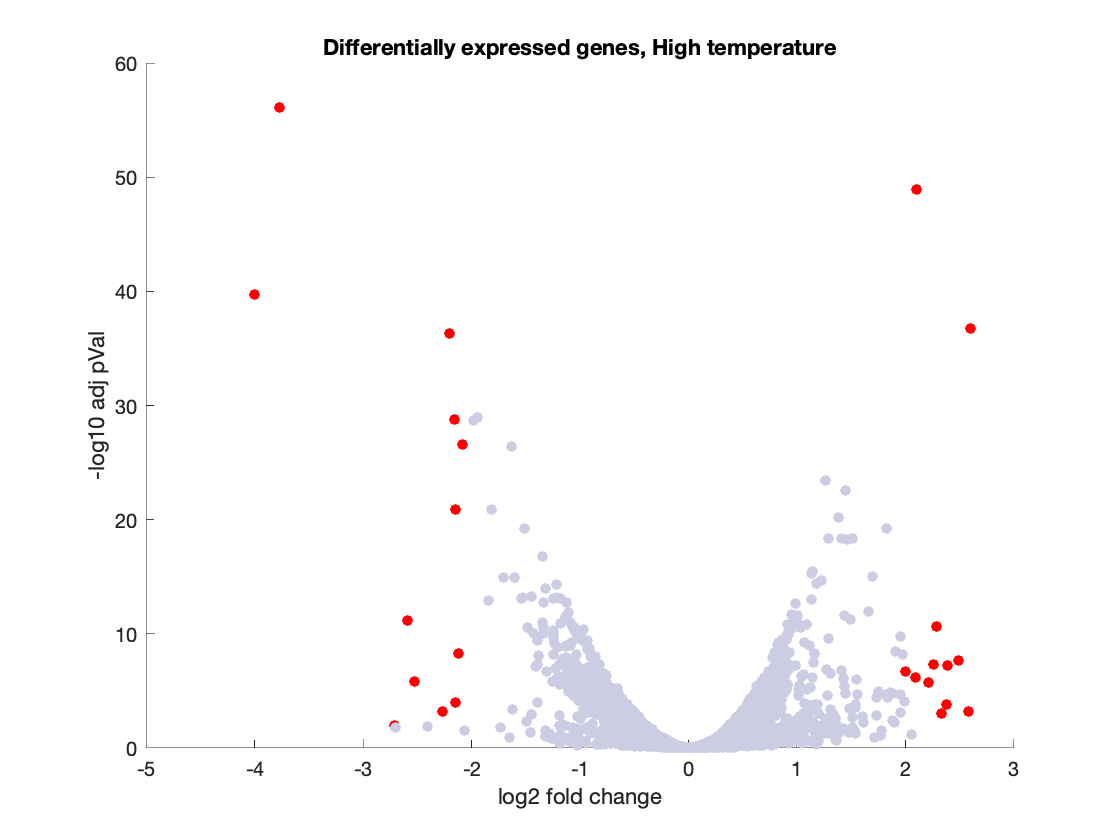

% pick one of the four stress condition that you would like to compare to
% the control
normCountsStress  = normalized_array(:,4:6); % HighTemperature
normCountsref     = normalized_array(:,1:3); % Control

% perform the test for differential expression using a negative binomial model
tLocal = nbintest(normCountsref, normCountsStress, 'VarianceLink', 'LocalRegression');
% correct for multiple testing using the Benjamini Hochberg correction
padj = mafdr(tLocal.pValue, 'BHFDR', true);

% create overview table of the results including the mean for both
% conditions, the resulting log2 fold change and the calculated pValue 
meanRef    = mean(normCountsref, 2);
meanStress = mean(normCountsStress, 2);
log2FC     = log2(meanStress./meanRef);
geneTable  = table(meanRef, meanStress, log2FC, tLocal.pValue, padj);

% add row and column names
geneTable.Properties.RowNames = rnaseq_table.GeneName(all(rnaseq_array, 2),:);
geneTable.Properties.VariableNames = {'Mean_Ref', 'Mean_Stress', 'Log2_FC', 'pVal', 'adjPVal'};
% create a volcano plot for visual inspection of the data
figure
hold on
xlabel('log2 fold change'); ylabel('-log10 adj pVal'); title('Differentially expressed genes, High temperature');
geneTable.color = repmat([0.80 0.80 0.89], height(geneTable), 1);
de_genes_index = geneTable.adjPVal <= 0.01 & abs(geneTable.Log2_FC) >= 2;
geneTable.color(de_genes_index, :) = repmat([1 0 0], nnz(de_genes_index), 1);
volcano = scatter(geneTable.Log2_FC, -log10(geneTable.adjPVal), 30, geneTable.color, 'fill');
hold off

**a)** Plot your results in a volcano plot, highlighting with a different color the differentially expressed genes. Explain in some lines how a volcano plot can be interpreted.

The x axis represents the fold change, ie the difference in the mean level of normalized expression between the stress condition and the normal condition. The genes where this absolute value is less than 2 are greyed out becaues the difference of expression is not considered large enough.

The y axis represents the adjusted p value, transformed via -log10. We are interested in selecting the genes for which their values are highly unlikely (improbable) to have been differentially expressed at those levels by random random chance, which is an adjusted p-value under 0.01. By trasnforming this with -log10, the genes of interest are plotted in the upper part of the chart.

**b)** How many down and up regulated genes were obtained?

The number of upregulated genes is:

disp(nnz(geneTable.adjPVal <= 0.01 & geneTable.Log2_FC >= 2));

    12



and the number of downregulated genes is:

disp(nnz(geneTable.adjPVal <= 0.01 & geneTable.Log2_FC <= -2));

    12



summing up to a total of

disp(nnz(de_genes_index));

    24



**c)** How are the results from these plots similar to or different from the results from the PCA plot?

The volcano plot focuses on a single stress condition and highlights specific genes, whereas the PCA plot shows how all the different conditions (and control) relate to each other.

**4.** Explore your DE analysis results and combine them with gene descriptions information available in the exercise data subfolder (see the MATLAB script).

**a)** Provide the gene identifiers, names and functions for your top 10 differentially expressed genes.

top_10_genes = sortrows(geneTable, 'adjPVal', 'ascend');
top_10_genes = top_10_genes(1:10, :);
% top_10_genes.ids = top_10_genes.Row;
gene_descriptions = readtable('data/GeneDescriptions.csv');
gene_descriptions.Row = gene_descriptions.GeneName;
top_10_genes = innerjoin(top_10_genes, gene_descriptions, 'Keys', {'Row'});
disp(top_10_genes(:,8:end));

                 geneSymbol               GeneDescription          
               ______________    __________________________________

    RDN5-1     {'RDN5-1'    }    {0×0 char                        }
    YAR020C    {'PAU7'      }    {'seriPAUperin family'           }
    YDR536W    {'STL1'      }    {'Sugar Transporter-Like protein'}
    YEL049W    {'PAU2'      }    {'seriPAUperin family'           }
    YHR092C    {'HXT4'      }    {'HeXose Transporter'            }
    YJR094C    {'IME1'      }    {'Inducer of MEiosis'            }
    YLL053C    {0×0 char    }    {0×0 char                        }
    YPL058C    {'PDR12'     }    {'Pleiotropic Drug Resistance'   }
    YPL171C    {'OYE3'      }    {'Old Yellow Enzyme'             }
    YPL187W  

**b)** Can you infer any interesting/meaningful biological pattern from these top DE genes?

Without having more insight into how these genes relate to one another (eg how far off their are in the biological pathways), it is hard to infer any biological pattern.

`5.` `GO`` terms analysis.`

`a)`` Provide the associated ``GO`` term IDs ``and`` descriptions for the ``top DE gene for your stress condition.`

`There are multiple ways of picking the "top" D gene according to `[https://www.biostars.org/p/249448,](https://www.biostars.org/p/249448,) but this gene is both the most significant and the most differentially (under)expressed.

top_gene = top_10_genes{1,7}{1,1};

GoTerms_table = readtable('data/GoTermsMapping.txt','delimiter','\t');
GoTermsIDs    = unique(GoTerms_table.GoTerm);
GoTermsGeneMap = containers.Map();
for i = 1:height(GoTerms_table)
    key = GoTerms_table{i,'GeneName'}{1};
    if isKey(GoTermsGeneMap,key)
        GoTermsGeneMap(key) = [GoTermsGeneMap(key),GoTerms_table{i,'GoTerm'}{1}];
    else
        GoTermsGeneMap(key) = {GoTerms_table{i,'GoTerm'}{1}};
    end
end
associatedGoTerms = GoTermsGeneMap(top_gene);
disp(['Associated GO Terms for gene ', top_gene, ' ', associatedGoTerms]);

    'Associated GO Terms for gene '    'RDN5-1'    ' '    'GO:0002181'



GO = geneont('File','data/GoTerms.obo');
GoTermID         = (associatedGoTerms{1}(4:end));
GoTermName       = GO(str2double(GoTermID)).Terms.Name;
GoTermDefinition = GO(str2double(GoTermID)).Terms.Definition;
disp(['GO Term ', GoTermID, ' - ', GoTermName, ' : ', GoTermDefinition]);

GO Term 0002181 - cytoplasmic translation : "The chemical reactions and pathways resulting in the formation of a protein in the cytoplasm. This is a ribosome-mediated process in which the information in messenger RNA (mRNA) is used to specify the sequence of amino acids in the protein." [GOC:hjd]


`b)`` What can you learn ``from`` it? Compare the knowledge you got ``with`` the summary paragraph ``on`` the S. cerevisiae Genome ``Database``.`

`The database seeems to be a better source of annotation, but the GO definition is quite targeted to understading the activity of the gene.`

`6.`` Find enriched ``GO`` terms ``in`` differentially expressed genes subset.`

`a)` `Take`` the ``first`` associated ``GO`` term for the ``top`` DE gene ``in`` the dataset, provide the ``number`` of DE genes that this ``GO`` term ``is`` also associated ``with``.`

`b)`` provide the ``number`` of total genes (DE ``and`` non``-``DE) that this ``GO`` term ``is`` associated ``with``. Run a hypergeometric test ``in`` order ``to`` asses ``if`` the enrichment of this ``GO`` term ``in`` DE genes ``is`` statiscally ``significant``.`

`c``) Provide a list of ``GO`` term IDs ``and`` descriptions for all the significantly enriched ``GO`` terms (adjusted p``-``Value` `<=``0``.``01``) ``in`` your DE genes.`

`7.`` Bonus track (optional, ``value` `1``.``5`` points): ``As`` you may have realized, DE analysis together ``with` `GO`` terms enrichment analysis ``is`` a powerful tool for finding biological phenotype differences across different environmental conditions, however it ``is`` usually argued that results depend largely ``on`` the selected ``differential`` expression thresholds. ``Try` `to` `repeat` `point`` #``4` `in`` this exercise for different p``-``value` `and`` log2 fold``-``change threshold ``values`` (see the MATLAB script suggestion). What can you say about this, ``in`` terms of ``number`` of obtained DE genes? Which of the two parameters ``is`` affecting your results the most?`